datapath = ...
    {"/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220518_AchsensorHEK003_repeat/",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220519_AchsensorHEK_001_repeat/"...
    }

datapath = 1×3 cell array
    {["/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220518_AchsensorHEK003_repeat/"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220519_AchsensorHEK_001_repeat/"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220914AChsensorHEK004_repeat/"]}




StateYao_file = ...
    {"20220518_AchsensorHEK003_Analysis2022-09-10.mat",...
    "20220519_AchsensorHEK_001_Analysis2022-09-09.mat"...
    }

StateYao_file = 1×3 cell array
    {["20220518_AchsensorHEK003_Analysis2022-09-10.mat"]}    {["20220519_AchsensorHEK_001_Analysis2022-09-09.mat"]}    {["20220914AChsensorHEK004_Analysis2022-09-14.mat"]}


all_epochs = [2 3 4 5 6]; % all the epochs
drug_epochs = [2 3 4 5 6];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)

CyclePositions = [1 2]; % which cycle positions we want to analyze
baseline_acq_num = 5; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 5; % epoch based response calculation

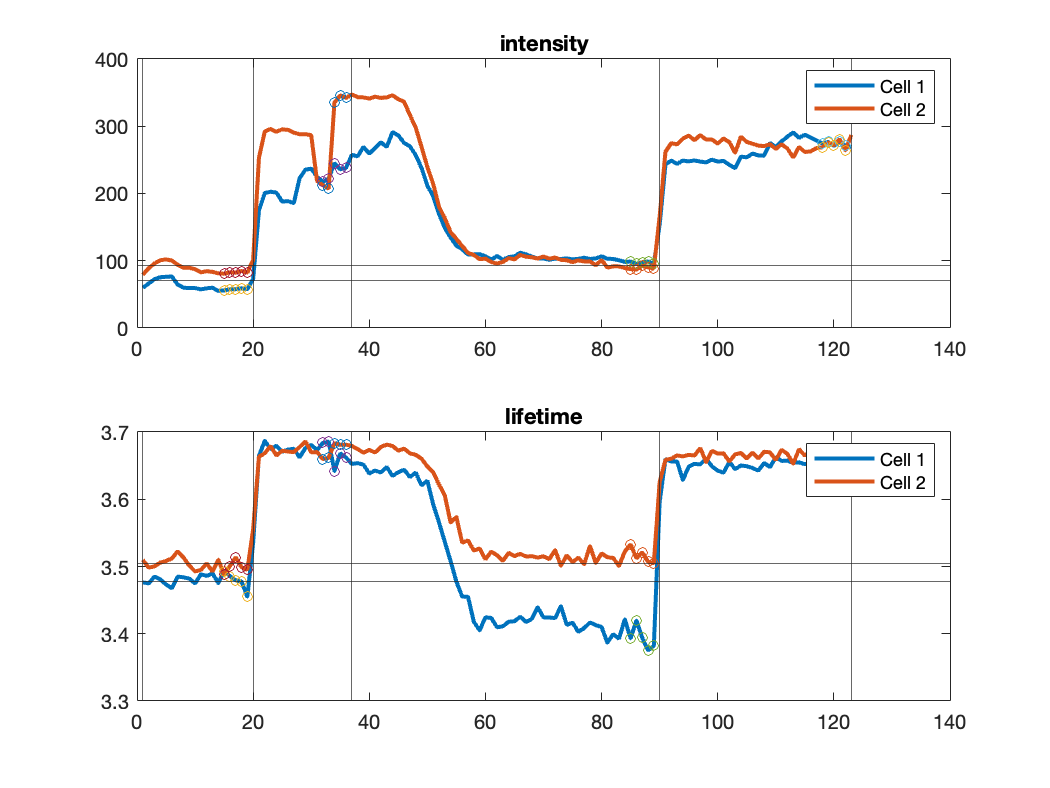

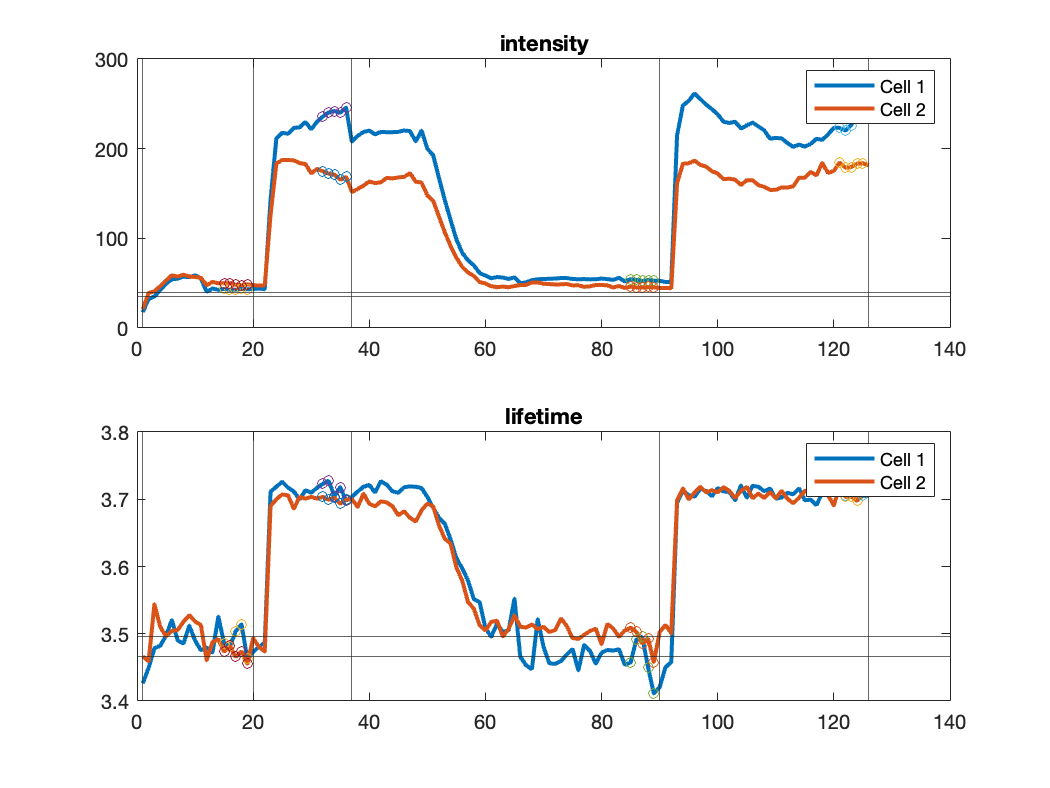

epoch_response_intensity_norm_all = 1×2 cell array
    {4×2 double}    {4×2 double}


epoch_response_lft_norm_all = 1×2 cell array
    {4×2 double}    {4×2 double}


epoch_response_intensity_all = 1×2 cell array
    {4×2 double}    {4×2 double}


epoch_response_lft_all = 1×2 cell array
    {4×2 double}    {4×2 double}


for i =1

    cd(datapath{i});
    load(StateYao_file{i});
    
    Yao_GUI_ReviseROIsBasedOnCoordinates(CyclePositions)
    CalculateROIBasedOnTopPixels(5, 0.66, CyclePositions)
    [lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels(CyclePositions);
    [epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all)
end

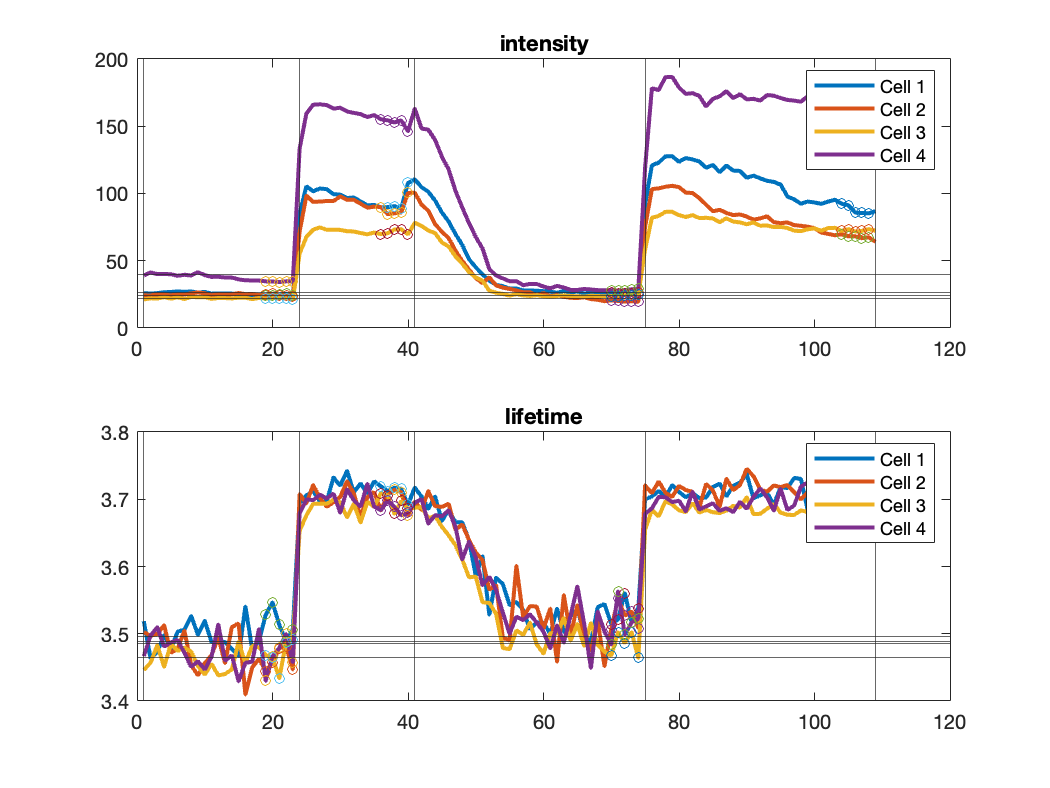

epoch_response_intensity_norm_all = 1×1 cell array
    {4×4 double}


epoch_response_lft_norm_all = 1×1 cell array
    {4×4 double}


epoch_response_intensity_all = 1×1 cell array
    {4×4 double}


epoch_response_lft_all = 1×1 cell array
    {4×4 double}


for i =2

    cd(datapath{i});
    load(StateYao_file{i});
    CyclePositions = [1];
    
    Yao_GUI_ReviseROIsBasedOnCoordinates(CyclePositions)
    CalculateROIBasedOnTopPixels(5, 0.6,CyclePositions)
    [lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels(CyclePositions);
    [epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all)
end